## Quantization

正常的 grayscale 有 256 階, 但有時候沒辦法有那麼多種顏色, 因此可以用 quantization 把 256 階轉為 n 階。以下把 256 階轉成 4 階

img = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_2\thylacine.png");
img_4 = grayslice(img, 4)

img_4 = 320×400 uint8 matrix
   1   1   1   2   2   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   1   2   1   1   2   1   2   2   1   0   1   2   2   1   1   1   2   2   1   1   1   2   1   1   2
   1   1   0   2   3   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   1   0   1   1   2   1   0   0   1   2   2   0   0   1   2   2   0   1   2   2   1   1   2
   0   1   1   2   2   1   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   3   2   0   0   1   2   2   1   0   1   2   2   1   0   0   2   2   1   0   1   3   2   1   2   1
   0   1   2   2   2   1   2   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   2   0   0   2   2   2   0   0   1   1   1   0   0   1   2   1   1   0   2   2   1   1   2   1
   1   2   3   3   1   1   3   2   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   1   1   0   0   2   1   0   1   0   2   1   0   1   1   1   2   

在這邊 0~63 被轉為 0, 64~127 被轉為 1, 128~191 被轉為 2, 192~256 被轉為 3。但要注意的是因為這些值都很接近 0，所以如果直接 ***imshow*** 的話會變成全黑, 所以要額外加指令。

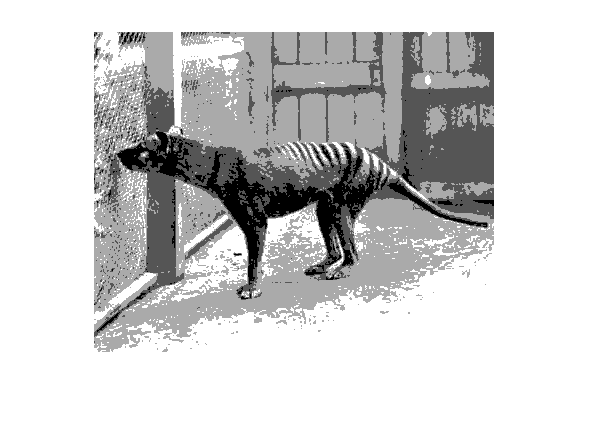

imshow(img_4, gray(4)) % 表示灰階 4 階

這張圖可以看到原本應該是同一個物體的地方 Ex. 後面的牆壁，多了很多不連續點，這個現象稱為 false contours，常常被用在醫學影像，藉由 quantization 來辨別出原本不明顯的特徵。

## Dithering

在顏色數量被限制下，如果想要盡可能的呈現原本的色階，避免 false contours 的情形，可以使用 Dithering。就是在 quantization 前先把原本的 matrix 與一個 dither matrix 做比較，概念上就是在顏色比較亮的地方就少塗幾格黑色、顏色比較暗的地方就多塗幾格黑色。如下圖

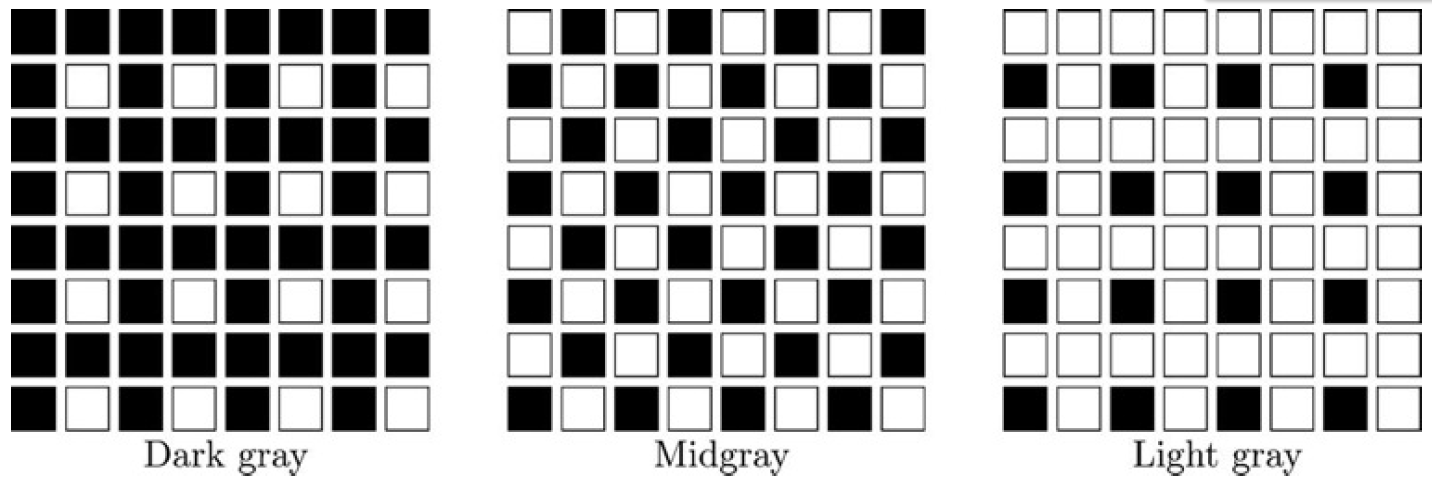

此圖中的 Dither matrix 就會是一個 2*2 的矩陣再重複放大到跟原圖矩陣一樣大

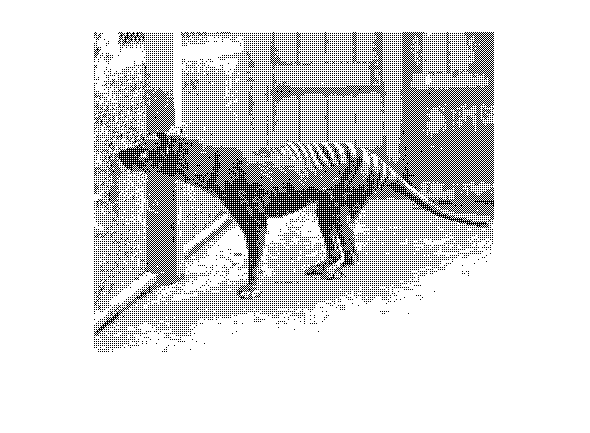

D = [0 128; 192 63];
DE = repmat(D, 160, 200);
img_di_2 = img > DE;
imshow(img_di_2)

可以發現此圖中雖然只有黑跟白兩種顏色, 可是卻用 dithering 做出了灰階的效果。

## Numerical Implementation

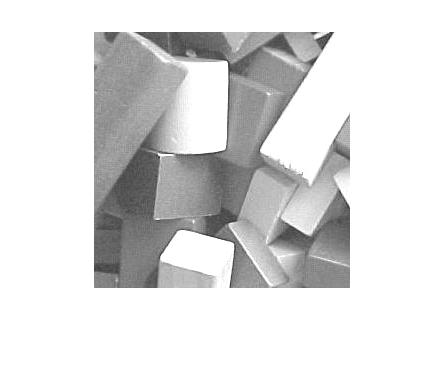

img = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\blocks.jpg");
img_bright = img + 64; % 變亮
imshow(img_bright)

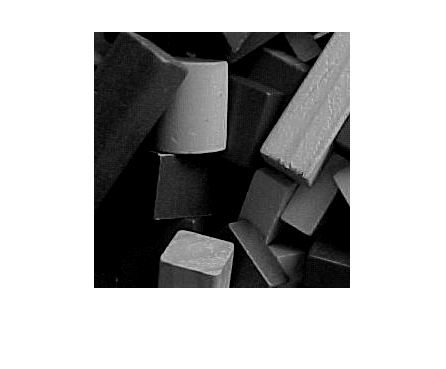

img_dark = img - 64; % 變暗
imshow(img_dark) 

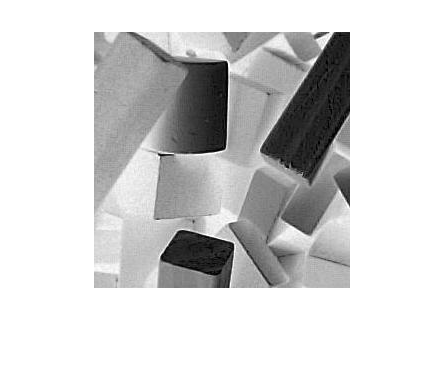

img_neg = 255 - img; % 負片效果
imshow(img_neg) 

## Histogram

藉由觀察顏色的 histogram, 我們便可以了解這張圖片的顏色分布及其性質。

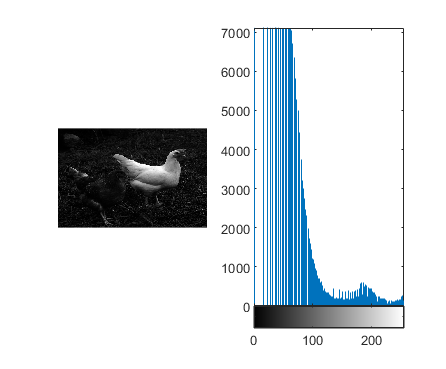

img = imread("D:\Dropbox\wave\In class\4thup\image processing\Original_Images_1\chickens.png");
subplot(1, 2, 1);
imshow(img)

subplot(1, 2, 2);
imhist(img)

從這個 histogram 可以看出這張照片整體的顏色偏暗, 對比也偏小(因為 histogram 過於集中)。因此我們可以用線性函數來調整這張圖。如果把原本灰階值 0~51 的部分拉至 0~256 (0~0.2 -> 0~1)，那就可以變成

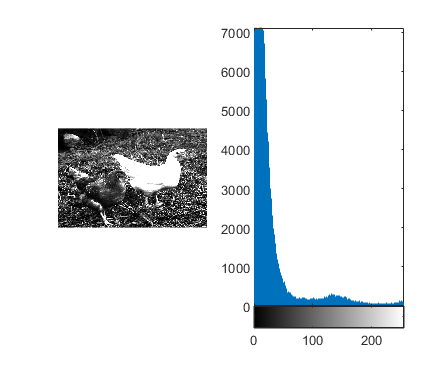

img_adj = imadjust(img, [0, 0.2], [0, 1]);
subplot(1, 2, 1)
imshow(img_adj)

subplot(1, 2, 2);
imhist(img_adj)

可以看到整張圖變清楚了，而且 historgram 也更加均勻。 或者也可以使用非線性的方式來映射，其公式為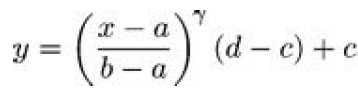

其中 $x$ 為原值, 從 $[a, b]$ 映射至 $[c, d]$, 而 $\gamma$ 舊式我們可以調整的值。它的意義如下

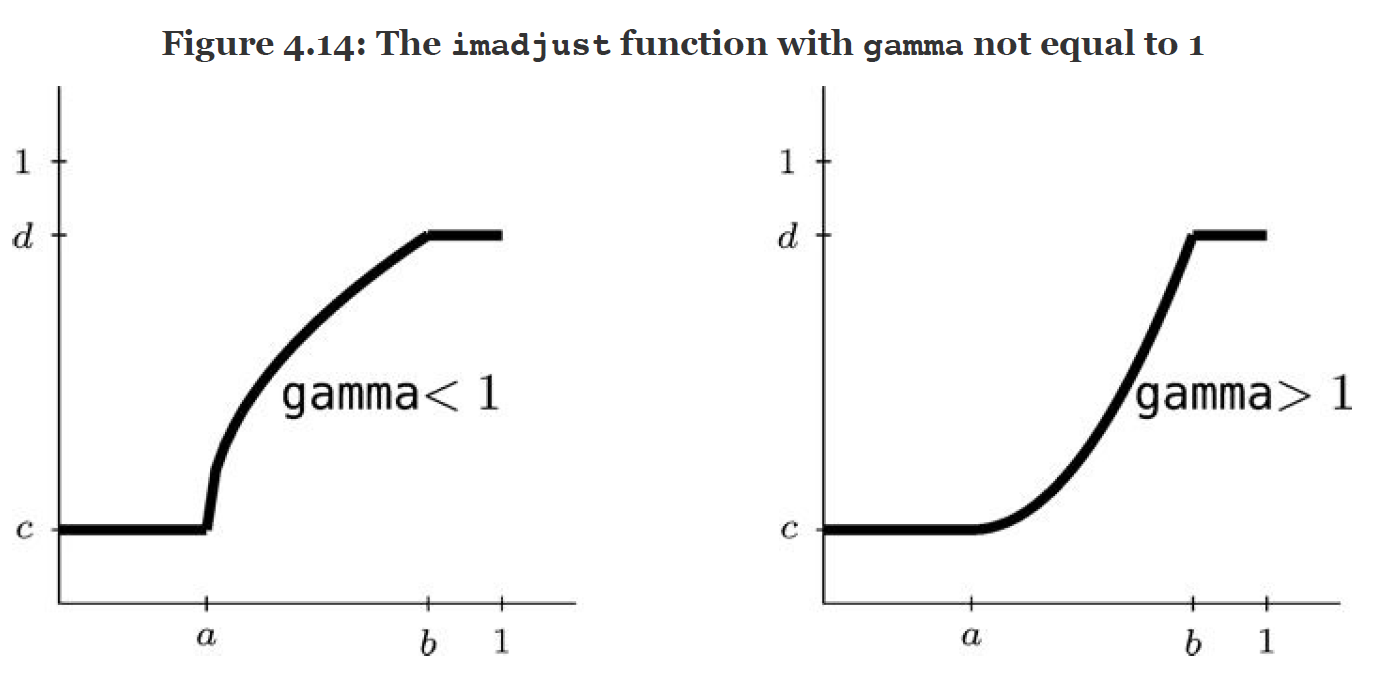

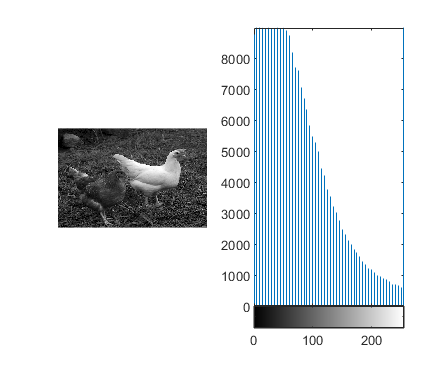

img_gamma_05 = imadjust(img, [], [], 0.5);
subplot(1, 2, 1)
imshow(img_gamma_05)

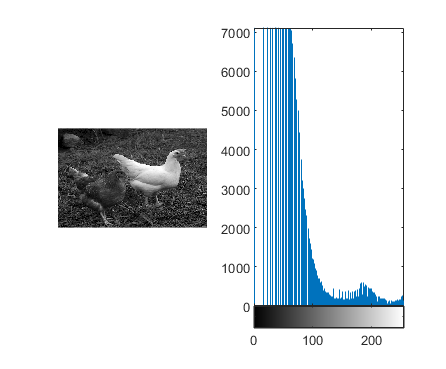

subplot(1, 2, 2);
imhist(img_gamma_05)

## Histogram Equalization

上面的 adjust 方法都需要輸入參數，另一種方法就是使用 histogram equalization 來自動調整，概念就是使用函數來使 histogram 盡量接近 uniform distribution。就由下列函數，原本的第 $i$ 階灰階值會變為

再四捨五入

其中 $n_i$ 為第 $i$ 階灰階值出現的次數, $n$ 為總 pixel 數, $L$ 為總灰階值個數。基本上概念就是拿 ECDF 乘上 range (起始為 0)，而這樣就可以使原本出現次數的很少的灰階值加起來去跟原本很多的灰階值平衡。

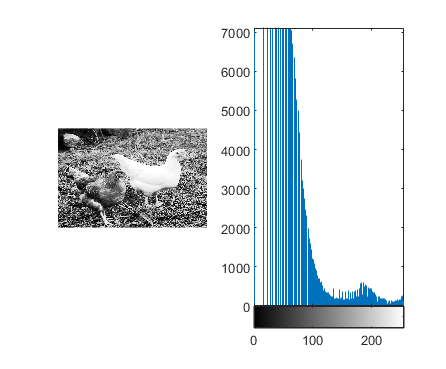

img_equ = histeq(img);
subplot(1, 2, 1)
imshow(img_equ)

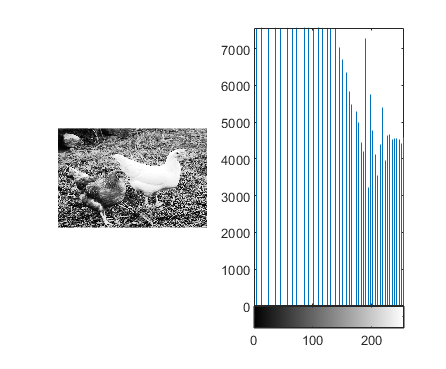

subplot(1, 2, 2);
imhist(img_equ)

可以看到圖片變得很清晰，而且 histogram 也變得比較均勻。